clear;clc;close all;
warning('off');
root_path = "D:\Document\EasyLM_RSBA\";
addpath(genpath(root_path))

% -------------- system config --------------
param.scale = 13;
param.measurement_noise = 0.5;
param.num_camera = 9;
param.H = 1080; % height of image in pixels
param.W = 1280; % width of image in pixels
param.fx = 1000; % focal length in pixels
param.fy = 1000; % focal length in pixels
param.cx = 640; % optical center
param.cy = 540;
param.K_matrix = [ param.fx 0 param.cx ; % Intrinsic camera parameter matrix
    0 param.fy param.cy ;
    0 0 1 ];
param.t_v = 0.00004625;
param.w_norm = 150;
param.d_norm = 10;
param.pitch = 0.01;
%param.pitch = 0.3;
param.num_error_of_line = 12;  %num points in the line
param.have_points = 0;
param.is_error_p = 1;
param.is_error_l = 0;
format long;

% -------------- generate camera param -------------
initialized_flag = false;
while ~initialized_flag
    try
        [camera_set, point_set, line_set, param, flag] = rs_simulate_line_pure_d(param);
        [camera_normal_set, param] = rs_simulate_normal(camera_set, param);

        if flag == 1
            disp('wd too large or scale too small');
            continue;
        end

        initialized_flag = true;
        disp('initialization success');

        gt_state_vector = raw2vec_pure_d(camera_set, point_set, param, true);
        initial_state_vector = raw2vec_pure_d(camera_set, point_set, param, false);
        gt_normal_state_vector = raw2vec_pure_d(camera_normal_set, point_set, param, true);
        initial_normal_state_vector = raw2vec_pure_d(camera_normal_set, point_set, param, false);
        % unit_direction
        unit_dir = find_unit_dir(gt_state_vector);
        newmodel_initial_state_vector = change_vector_model(initial_state_vector, param, unit_dir, 1);
        initial_state_vector1 = change_vector_model(newmodel_initial_state_vector, param, unit_dir, 0);

        % unit_direction
        unit_dir_normal = find_unit_dir(gt_normal_state_vector);
        newmodel_initial_normal_state_vector = change_vector_model(initial_normal_state_vector , param, unit_dir_normal, 1);
        initial_normal_state_vector1 = change_vector_model(newmodel_initial_normal_state_vector, param, unit_dir_normal, 0);
    

        gt_state_vector_line = raw2vec_line_pure_d(camera_set, point_set, line_set, param, true);             
        initial_state_vector_line = raw2vec_line_pure_d(camera_set, point_set, line_set, param, false);
        gt_normal_state_vector_line = raw2vec_line_pure_d(camera_normal_set, point_set, line_set, param, true);
        initial_normal_state_vector_line = raw2vec_line_pure_d(camera_normal_set, point_set, line_set, param, false);

        % unit_direction
        unit_dir_normal_line = find_unit_dir(gt_normal_state_vector_line);
        newmodel_initial_normal_state_vector_line = change_vector_model_line(initial_normal_state_vector_line, param, unit_dir_normal_line, 1);
        initial_normal_state_vector_line1 = change_vector_model_line(newmodel_initial_normal_state_vector_line, param, unit_dir_normal_line, 0);
        disp('begin')
    catch
        disp('initialization fail error!!!');
        continue;
    end
end

initialization success


begin


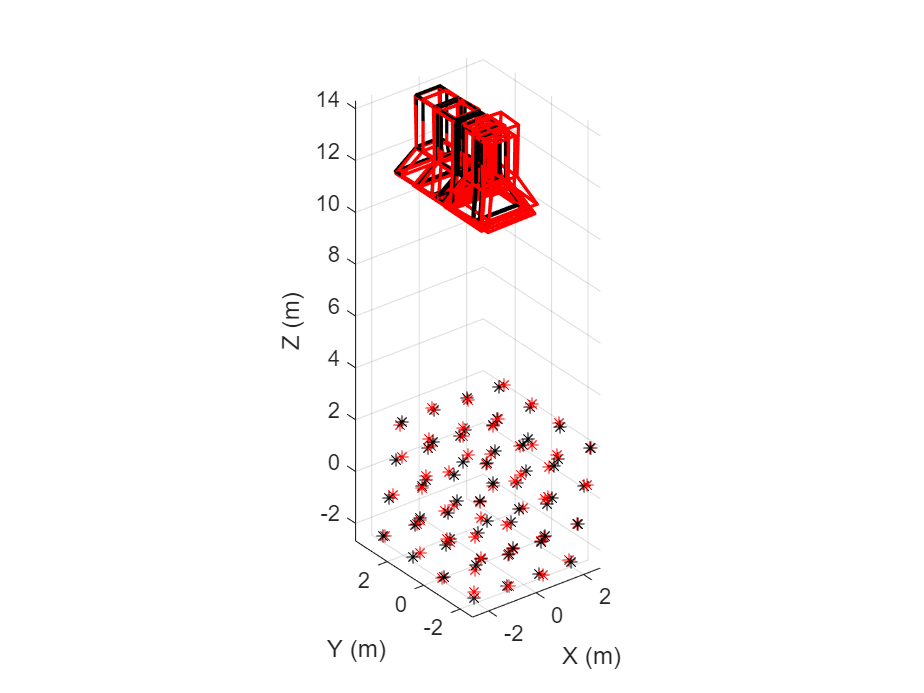

plot_cell = cell(1,2);
plot_gt.camera_state_vector = gt_state_vector;
plot_gt.point_state_vector = point_set.point_gt;
plot_gt.color = "black";
plot_cell{1, 1} = plot_gt;
plot_gt.camera_state_vector = initial_state_vector;
plot_gt.point_state_vector = point_set.point;
plot_gt.color = "red";
plot_cell{1, 2} = plot_gt;
plot3d_rs(plot_cell, param);

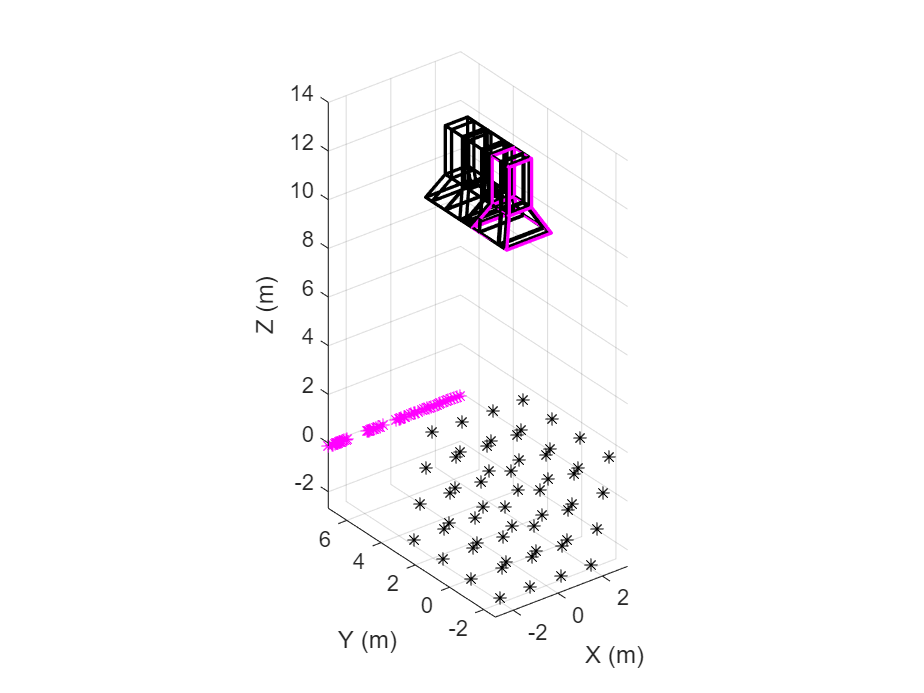

% % -------------- mrsba --------------

refined_state_vector = mrsba_easylm_solver_pure_d(camera_set, newmodel_initial_state_vector, param);
refined_state_vector = change_vector_model(refined_state_vector, param, unit_dir, 0);
refined_state_vector_p = refined_state_vector;
plot_cell = cell(1,2);
plot_gt.camera_state_vector = gt_state_vector;
plot_gt.point_state_vector = point_set.point_gt;
plot_gt.color = "black";
plot_cell{1, 1} = plot_gt;
point = getPoint(refined_state_vector, param);
plot_gt.camera_state_vector = refined_state_vector;
plot_gt.point_state_vector = point;
plot_gt.color = 'magenta';
plot_cell{1, 2} = plot_gt;
plot3d_rs(plot_cell, param);

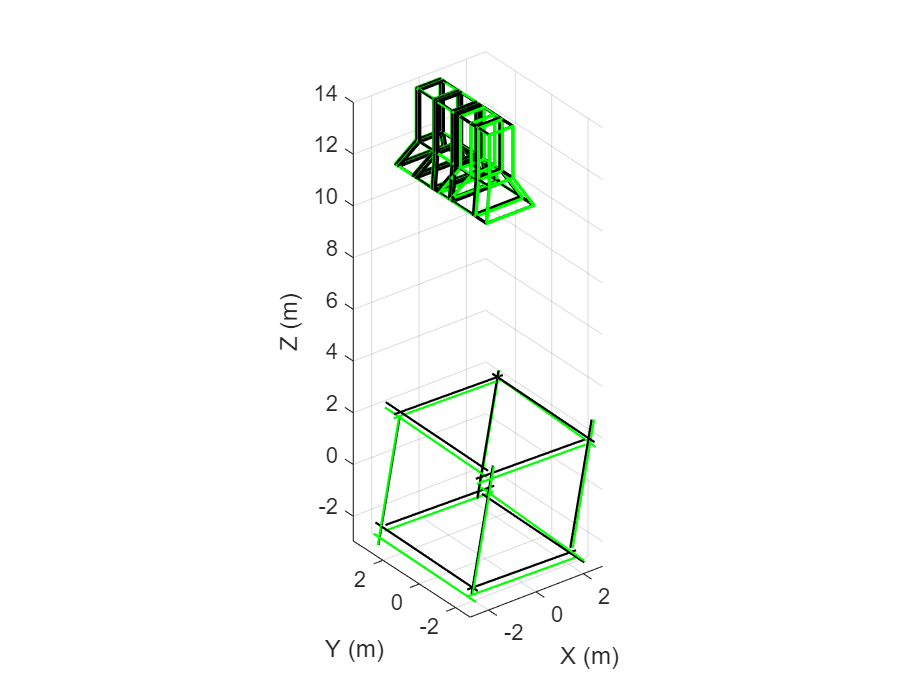

%  % -------------- nlrsba2 --------------
param.rs_line_ba = 2;
param.have_points = 0;
param.is_error_p = 0;
param.is_error_l = 1;
refined_state_vector = nlrsba_easylm_solver_pure_d(camera_set, newmodel_initial_normal_state_vector_line , param);
refined_state_vector = change_vector_model_line(refined_state_vector, param, unit_dir_normal_line, 0);
plot_cell = cell(1,2);
plot_gt.camera_state_vector = gt_normal_state_vector_line;
plot_gt.line_state_vector = line_set.line_gt;
plot_gt.color = "black";
plot_cell{1, 1} = plot_gt;
line = getLine(refined_state_vector, param);
plot_gt.camera_state_vector = refined_state_vector;
plot_gt.line_state_vector = line;
plot_gt.color = "green";
plot_cell{1, 2} = plot_gt;
plot3d_line_rs(plot_cell, param);

% ----------- mrsba -----------
function refined_state_vector = mrsba_easylm_solver_pure_d(camera_set, initial_state_vector, param)
    solver = EasyLM_pure_d(@(x)f_mrsba_opter_pure_d(x, camera_set, param), @(x, dx)so3_rsba_update_func(x, dx, param), 'SpecifyObjectiveGradient', false, 'FixParameter', [1 2 3 4 5 6 7 8 9 10]);
    refined_state_vector = solver.solve(initial_state_vector);
end


% -------------------nlrsba-------------------
function refined_state_vector = nlrsba_easylm_solver_pure_d(camera_set, initial_state_vector, param)
    solver = EasyLM_pure_d(@(x)f_nlrsba_opter_pure_d(x, camera_set, param), @(x, dx)so3_rsba_update_func(x, dx, param), 'SpecifyObjectiveGradient', false, 'FixParameter', [1 2 3 4 5 6 7 8 9 10]);
    refined_state_vector = solver.solve(initial_state_vector);
end

